% build SRCNN using deep learning graph
lgraph = layerGraph();
tempLayers = [
    imageInputLayer([130 130 1],"Name","data")
    convolution2dLayer([3 3],64,"Name","conv1","Padding","same")
    reluLayer("Name","relu_conv1")
    convolution2dLayer([3 3],64,"Name","conv2","Padding","same")
    reluLayer("Name","relu_conv2")
    resize2dLayer("Name","upSampling1","Scale",2)
    maxPooling2dLayer([3 3],"Name","pool1")
];
lgraph = addLayers(lgraph,tempLayers);
tempLayers = [
    convolution2dLayer([3,3],128,"Name","conv3","Padding","same")
    reluLayer("Name","relu_conv3")
    convolution2dLayer([3 3],128,"Name","conv4","Padding","same")
    reluLayer("Name","relu_conv4")
    resize2dLayer("Name","upSampling2","Scale",2)
    maxPooling2dLayer([3 3],"Name","pool2")
];
lgraph = addLayers(lgraph,tempLayers);
tempLayers = [
    convolution2dLayer([5,5],1,"Name","conv5","Padding","same")
    regressionLayer("Name","Routput")
];
lgraph = addLayers(lgraph,tempLayers);
clear tempLayers;

% connect layers to construct network graph
lgraph = connectLayers(lgraph,"pool1","conv3");
lgraph = connectLayers(lgraph,"pool2","conv5");

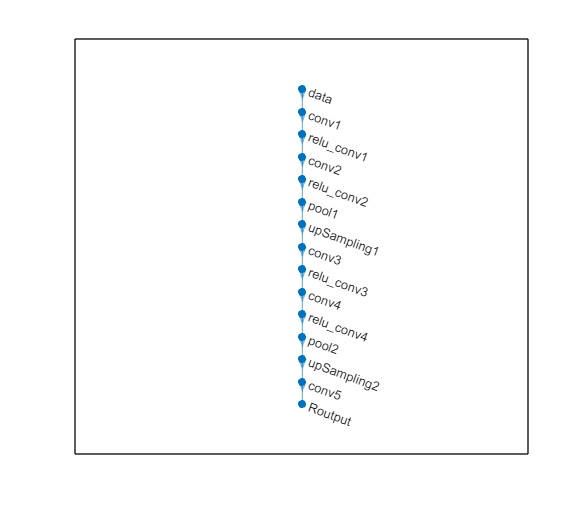

% plot our SRCNN
plot(lgraph)

% analyze
analyzeNetwork(lgraph)

% prepare the data
trainingsetoutput = zeros(514,514,1,300);
trainingsetinput = zeros(130,130,1,300);
for i = 1:300
    data = fitsread("data\ts ("+num2str(i)+").fits");
    trainingsetoutput(:,:,1,i) = imresize(data, [514,514]);
    resized_data = imresize(data, [130,130]);
    trainingsetinput(:,:,1,i) = resized_data;
end

% set our training options
options = trainingOptions("adam", ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.2, ...
    LearnRateDropPeriod=10, ...
    MaxEpochs=25, ...
    MiniBatchSize=6, ...
    InitialLearnRate=1e-5, ...
    Plots="training-progress")

options =   TrainingOptionsADAM - 属性:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-05
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.2000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 25
                   MiniBatchSize: 6
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'

在单 GPU 上训练。
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　小批量损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０４　｜　　　　　　　９．６８　｜　　　　４６．８　｜　１．００００ｅ－０５　｜
｜　　　１　｜　　　５０　｜　　　　　００：０１：２４　｜　　　　　　５０．３８　｜　　１２６９．１　｜　１．００００ｅ－０５　｜
｜　　　２　｜　　１００　｜　　　　　００：０２：４３　｜　　　　　　４３．３７　｜　　　９４０．３　｜　１．００００ｅ－０５　｜
｜　　　３　｜　　１５０　｜　　　　　００：０４：０４　｜　　　　　　３５．４３　｜　　　６２７．５　｜　１．００００ｅ－０５　｜
｜　　　４　｜　　２００　｜　　　　　００：０５：２６　｜　　　　　　２８．１０　｜　　　３９４．８　｜　１．００００ｅ－０５　｜
｜　　　５　｜　　２５０　｜　　　　　００：０６：４４　｜　　　　　　２３．７８　｜　　　２８２．７　｜　１．００００ｅ－０５　｜
｜　　　６　｜　　３００　｜　　　　　００：０８：０８　｜　　　　　　２２．２２　｜　　　２４６．８　｜　１．００００ｅ－０５　｜
｜　　　７　｜　　３５０　｜　　　　　００：０９：３０　｜　　　　　　２１．６４　｜　　　２３４．１　｜　１．００００ｅ－０５　｜
｜　　　８　｜　　４００　｜　　　　　００：１０：４８　｜　　　　　　２１．３２　｜　　　２２７．２　｜　１．００００ｅ－０５　｜
｜　　　９　｜　　４５０　｜　　　　　００：１２：０５　｜　　　　　　２１．０８　｜　　　２２２．３　｜　１．００００ｅ－０５　｜
｜　　１０　｜　　５００　｜　　　　　００：１３：２４　｜　　　　　　２０．９０　｜　　　２１８．３　｜　１．００００ｅ－０

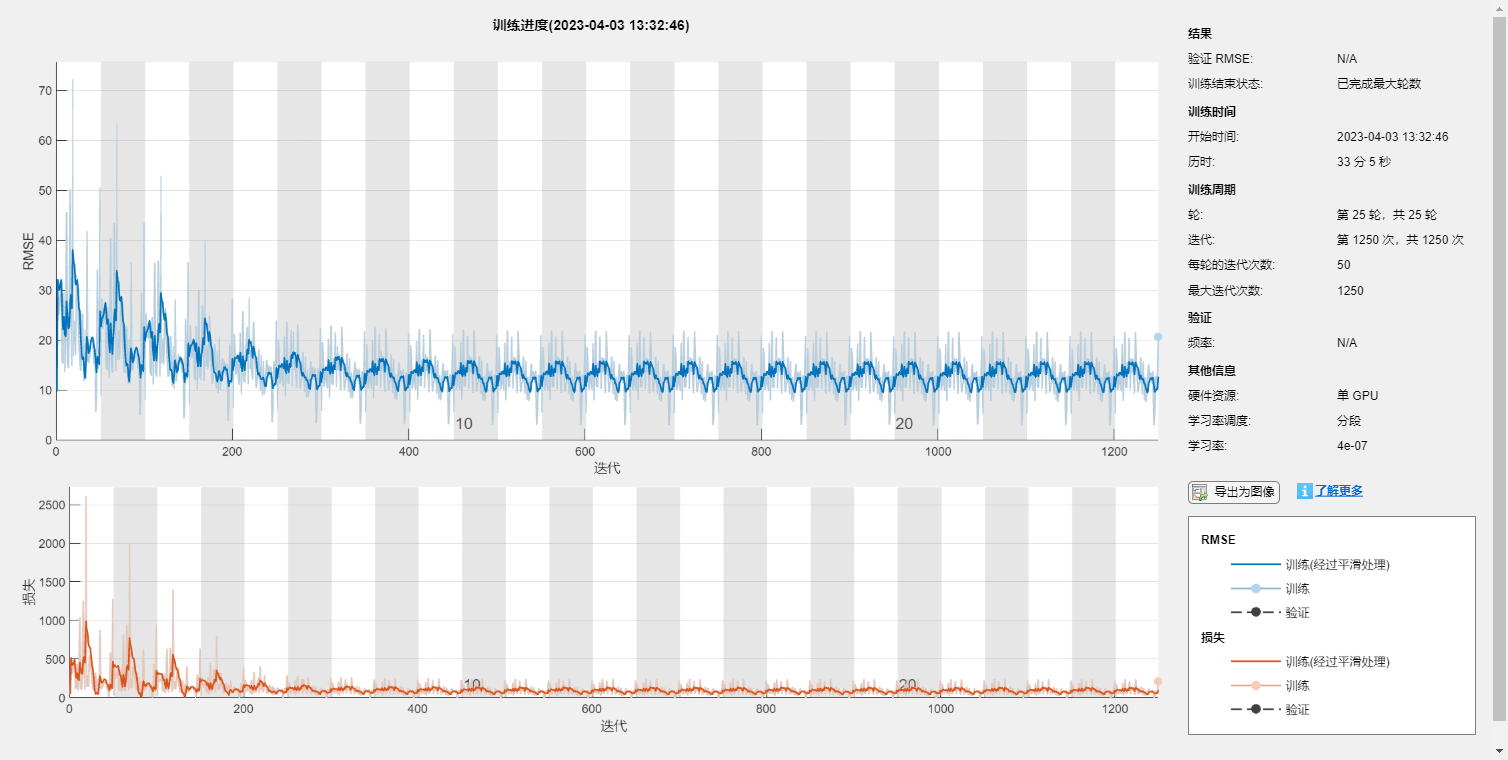

[net,info] = trainNetwork(trainingsetinput,trainingsetoutput,lgraph,options);

% prepare testing data
testingsetinput = zeros(130,130,1,149);
testingsetoutput = zeros(514,514,1,149);
for i = 1:149
    data = fitsread("testingset\test ("+num2str(i)+").fits");
    testingsetinput(:,:,1,i) = imresize(data, [130,130]);
    testingsetoutput(:,:,1,i) = imresize(data, [514,514]);
end

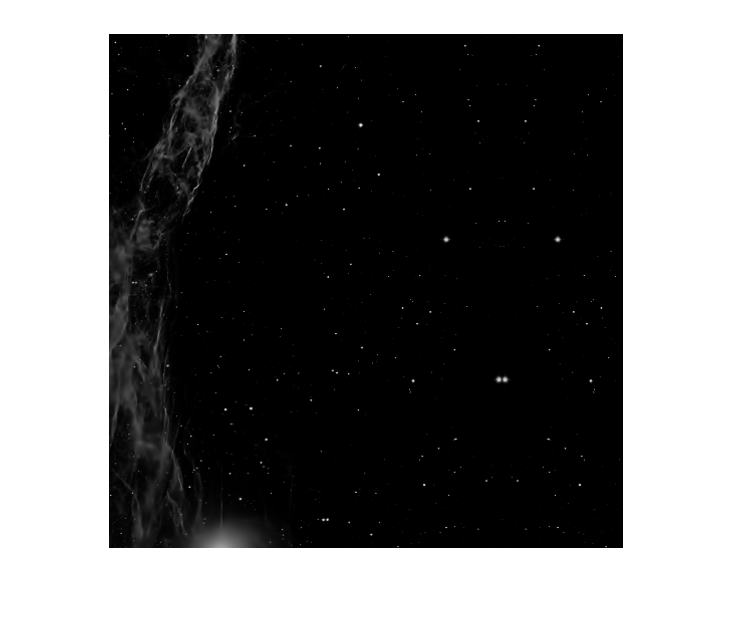

% test
test_id = 100;
test_image = testingsetoutput(:,:,1,test_id);
imshow(test_image)

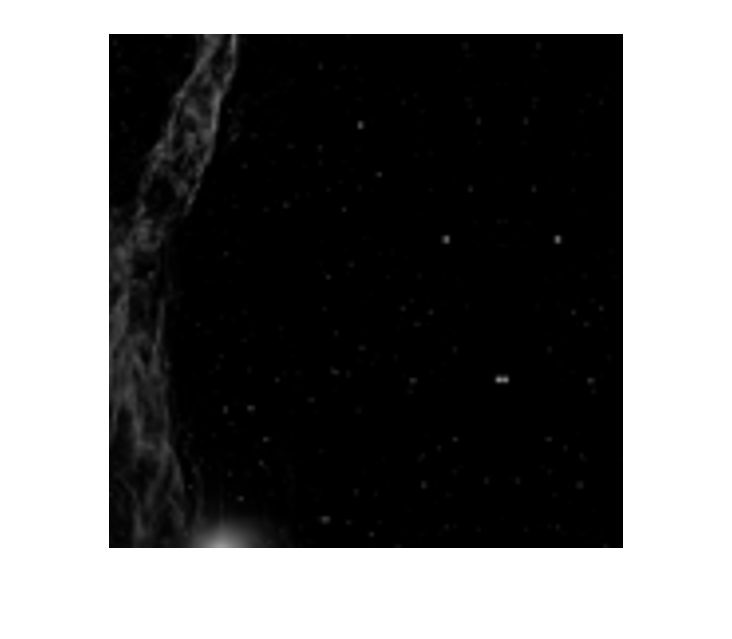

bicubic_test_image = imresize(testingsetinput(:,:,1,test_id), [514,514],'bicubic');
imshow(bicubic_test_image)

psnr(bicubic_test_image, test_image)

ans = 33.2322

ssim(bicubic_test_image, test_image)

ans = 0.9132

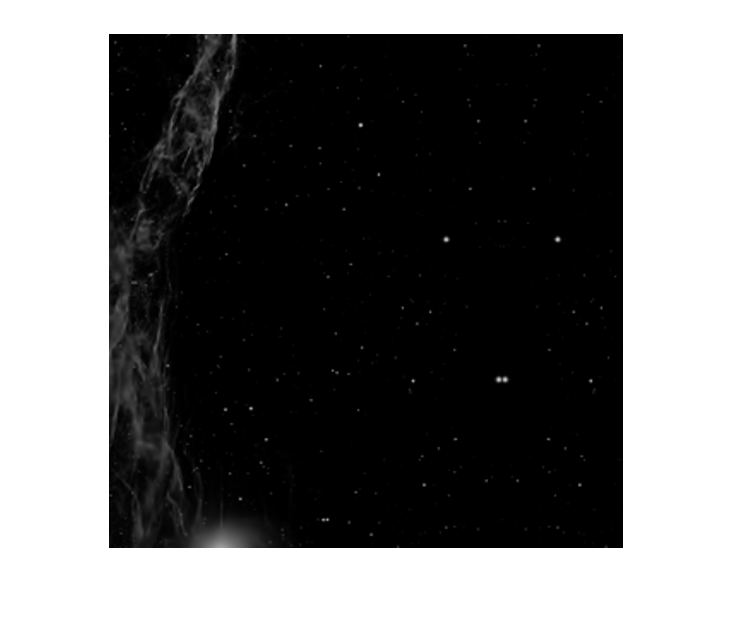

srcnn_image = double(net.predict(testingsetinput(:,:,1,test_id)));
imshow(srcnn_image)

psnr(srcnn_image, test_image)

ans = 37.9830

ssim(srcnn_image, test_image)

ans = 0.9729

% imresize(imresize(testingsetoutput(:,:,1,100),[300,300]),[514,514]);

% plot psnr and ssim curve
PSNRs = 38 - 0.2 * info.TrainingRMSE;
SSIMs = 0.9729 - 0.02 * info.TrainingRMSE;

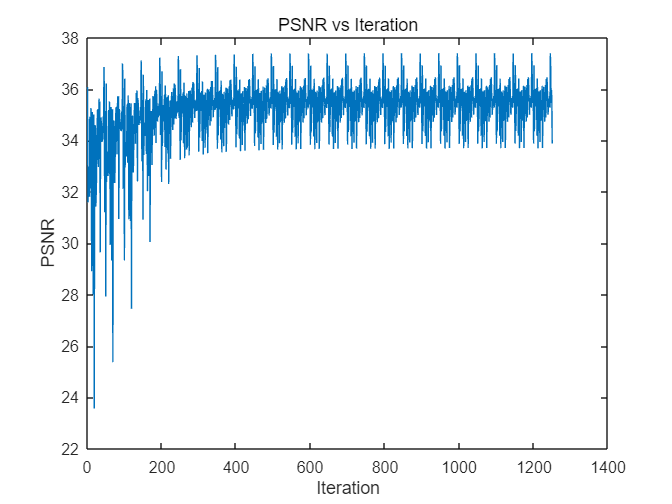

figure
plot(PSNRs)
xlabel("Iteration")
ylabel("PSNR")
title("PSNR vs Iteration")

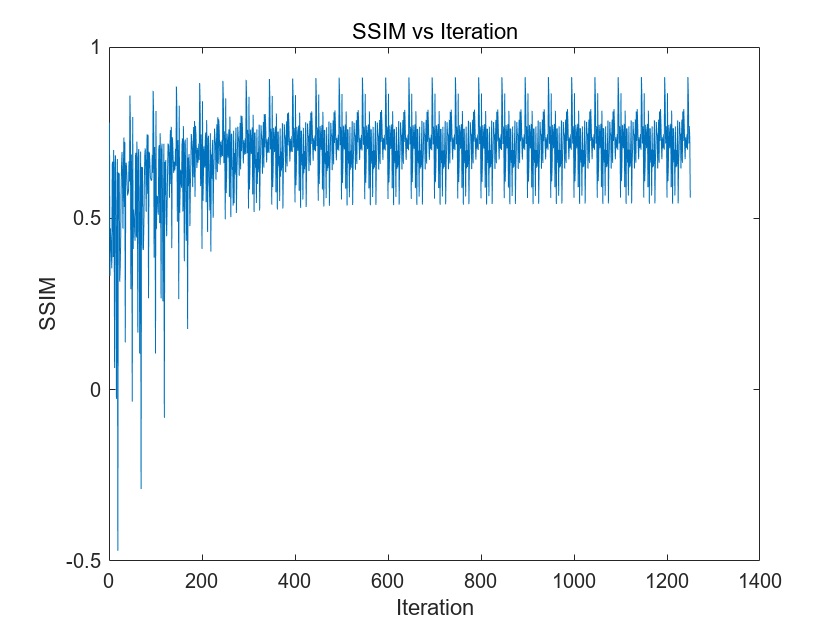

figure
plot(SSIMs)
xlabel("Iteration")
ylabel("SSIM")
title("SSIM vs Iteration")

% temporal evaluation
tic
net.predict(testingsetinput(:,:,1,test_id));
toc

历时 0.791988 秒。



tic
imresize(testingsetinput(:,:,1,test_id), [514,514],'bicubic');
toc

历时 0.006784 秒。
